# ECEN 5463 | EX 2

Collin Thornton

## Problem 1

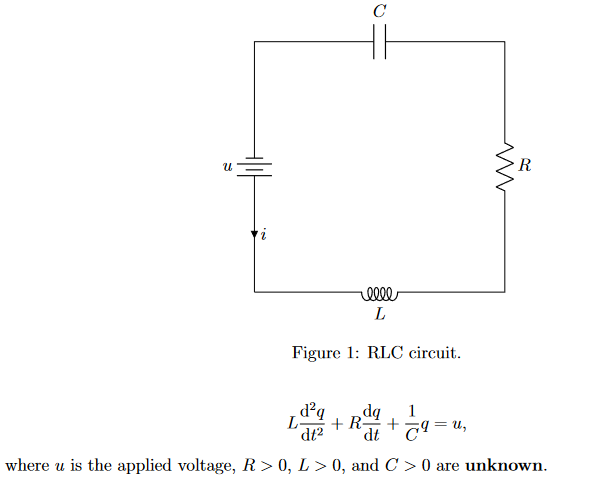

### 1.1 Design an implementable adaptive controller to drive the charge across the capacitor to 5 C. 

Closed Loop Dynamics:

$-L\ddot{e} -R\dot{e} +\frac{1}{C}\left(q_d -e\right)=u$, where $e=q_d -q$ and $q_d =5$

Let $r=\dot{e} +\alpha e$, $\theta =\left\lbrack \begin{array}{c}
\frac{1}{C}\\
R\\
L
\end{array}\right\rbrack$,  and $L\dot{r} =Y\left(e,r\right)\theta -u=L\ddot{e} +L\alpha \dot{e}$

Thus, $Y\left(e,r\right)=\left\lbrack \begin{array}{ccc}
q_d -q & -\dot{e}  & \alpha \dot{e} 
\end{array}\right\rbrack$.

Let $V\left(z\right)=\frac{1}{2}e^2 +\frac{L}{2}r^2 +\frac{1}{2}{\tilde{\theta} }^T \tilde{\theta}$, where $z=\left\lbrack \begin{array}{c}
e\\
r\\
\tilde{\theta} 
\end{array}\right\rbrack$ and $\tilde{\theta} =\theta -\hat{\theta}$ and $\hat{\theta}$ is the estimate of $\theta$.


$$\dot{V} \left(z\right)=\frac{\partial V\left(z\right)}{\partial z}\dot{z} =\left\lbrack \begin{array}{ccc}
e & \textrm{Lr} & {\tilde{\theta} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\dot{e} \\
\dot{r} \\
\dot{\tilde{\theta} } 
\end{array}\right\rbrack =e\dot{e} +\textrm{rL}\dot{r} +{\tilde{\theta} }^T \dot{\tilde{\theta} }$$



$$\dot{V} \left(z\right)=e\left(r-\alpha e\right)+r\left(Y\left(e,r\right)\theta -u\right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$



$$\dot{V} \left(z\right)=\textrm{er}-e^2 a+r\left(Y\left(e,r\right)\theta -u\right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$


We need to define $u$ and $\dot{\hat{\theta} }$ such that $\dot{V} \left(z\right)$is either negative definite or negative semidefinite.

Try $u=Y\left(e,r\right)\hat{\theta} +e+r$ and $\dot{\hat{\theta} } ={\textrm{rY}}^T \left(e,r\right)$


$$\dot{V} \left(z\right)=er-e^2 a+\textrm{rY}\left(e,r\right)\left(\theta -\hat{\theta} \right)-r^2 -er-{\tilde{\theta} }^T {\textrm{rY}}^T \left(e,r\right)$$



$$\dot{V} \left(z\right)=-e^2 a-r^2 +\textrm{rY}\left(e,r\right)\tilde{\theta} -{\tilde{\theta} }^T {\textrm{rY}}^T \left(e,r\right)$$



$$\dot{V} \left(z\right)=-e^2 a-r^2$$


$\dot{V} \left(z\right)\le 0$ on the line $z=\left\lbrack \begin{array}{c}
0\\
0\\
\tilde{\theta} 
\end{array}\right\rbrack$. Now we must apply the invariance principle to further evaluate the equilibrium point. See below for an analysis of the hypotheses of Corollary 90.

**1.)** $D\subset\mathbb{R}^5$ is an open set. Here, $D=\mathbb{R}^5$ as $V\left(z\right)>0\;$  $\forall z\in\mathbb{R}^5$ and $\dot V(z) \leq 0 ~~\forall z\in\mathbb{R}^5$

**2.) **$\dot{z} =g\left(z\right)$ is locally Lipschitz. This is true as all components of $g\left(z\right)={\left\lbrack \begin{array}{ccc}
\dot{e}  & \dot{r}  & \dot{\tilde{\theta} } 
\end{array}\right\rbrack }^T$ are locally Lipschitz.

**3.)** $V\left(z\right)$ is continuously differentiable

**4.) **By Claim 64 and acknowledging that $V\left(z\right)$ is radially unbounded, given any $\beta >0$, $\Omega_{\beta }^{\prime }$ is a filled ellipse, compact, connected, and in $D=\mathbb{R}^5$ and is positively invariant. Let $\Omega =\Omega_{\beta }^{\prime }$ for any $\beta >0$.

**5.) **$\dot{V} \left(z\right):=\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)\le 0,\;\;\;\forall x\in \Omega$. This is true as $\dot{V} \left(z\right)$ was designed to be negative semidefinite.

**6.)** $E=\left\lbrace z\in \Omega \;|\;\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)=0\right\rbrace =\Omega \cap \left\lbrace \left\lbrack \begin{array}{c}
e\\
r\\
\tilde{\theta} 
\end{array}\right\rbrack \in R^5 \;\;|\;\;e,r=0\right\rbrace$

**7.) **Find $M\subset E$, where $M$ is the largest invariant set in $E$.

Let's rewrite the dynamics:


$$\dot{e} =r-\alpha e$$



$$\dot{r} =\frac{\left(Y\left(e,r\right)\theta -u\right)}{L}=\frac{Y\left(e,r\right)\tilde{\theta} -e-r}{L}$$



$$\dot{\tilde{\theta} } =-\dot{\hat{\theta} } =-{\mathrm{rY}}^T \left(e,r\right)$$


***Note:*** $Y\left(e,r\right)=\left\lbrack \begin{array}{ccc}
q_d  & \alpha e-r & \alpha \left(r-\alpha e\right)
\end{array}\right\rbrack$

We know that, as the origin is an equilibrium point, $M$ must include the set $\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack \right\rbrace$.  To see if we can find a larger invariant set, let $\zeta^0 =\left\lbrack \begin{array}{c}
0\\
0\\
\tilde{\theta} 
\end{array}\right\rbrack$. Then at $t=0$, $g\left(z\right)=\left\lbrack \begin{array}{c}
r-\alpha e\\
\frac{Y\left(e,r\right)\tilde{\theta} -e-r}{L}\\
-{\mathrm{rY}}^T \left(e,r\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
\frac{q_d \tilde{\theta_1 } }{L}\\
0
\end{array}\right\rbrack$. The second term is clearly only $0$ if $q_d \tilde{\theta_1 } =0$. 

Thus $M=\left\lbrace \left\lbrack \begin{array}{c}
e\\
r\\
\tilde{\theta_1 } \\
\tilde{\theta_2 } \\
\tilde{\theta_3 } 
\end{array}\right\rbrack \in \Re^5 \;\;|\;\;e,r,\tilde{\theta_1 } =0\right\rbrace$  and $M\subset E$. Given any $\zeta^0 \in \Omega$, $\lim_{t\to \infty } \;\mathrm{dist}\left(\phi \left(t,\zeta^0 \right),M\right)=0$ and $\lim_{t\to \infty } \;\phi_e \left(t,\zeta^0 \right)=0$. In other words, the the angular position will approach the setpoint when $\zeta^0 \in \Omega$.

As $V\left(z\right)$is radially unbounded, we can pick an arbitrarily large $\beta$ such that $\zeta^0 \in \Omega_{\beta }^{\prime }$. Letting $\Omega =\Omega_{\beta }^{\prime }$ shows **global asymptotic stability (GAS).**

### 1.2 Bonus

 In order to show that $\hat{\theta_1 }$ converges to $\frac{1}{C}$, let us use $Y\left(e,r\right)$. We defined $Y\left(e,r\right)$ such that $L\dot{r} =Y\left(e,r\right)\theta -u$. We've already shown GAS of the origin. In order for $r$ to stay at the origin, $\dot{r}$ must also be $0$. This implies that 


$$0=Y\left(e,r\right)\theta -Y\left(e,r\right)\hat{\theta} -e-r$$


$0=Y\left(e,r\right)\tilde{\theta}$           As $e,r=0$


$$0=\left\lbrack \begin{array}{ccc}
q_d  & \alpha e-r & \alpha \left(r-\alpha e\right)
\end{array}\right\rbrack \tilde{\theta}$$


$0=\left\lbrack \begin{array}{ccc}
q_d  & 0 & 0
\end{array}\right\rbrack \tilde{\theta}$     As $e,r=0$

Thus, we have proven that $\tilde{\theta_1 } q_d =0$ and $\tilde{\theta_1 }$ will converge to $0$ as the system approaches equilibrium. If $q_d \;\not= 0$, this shows that $\hat{\theta_1 }$ converges to $\frac{1}{C}$.

### 1.3 Simulate the controller to show that it works as expected. 

This will generate two plots show the controller working with randomized parameter values, estimates, and initial conditions. Notice that $\tilde{\theta} \to 0$ over the course of the simuation. This proves that $\hat{\theta} \to \frac{1}{C}$ and that the  bonus is satisfied.

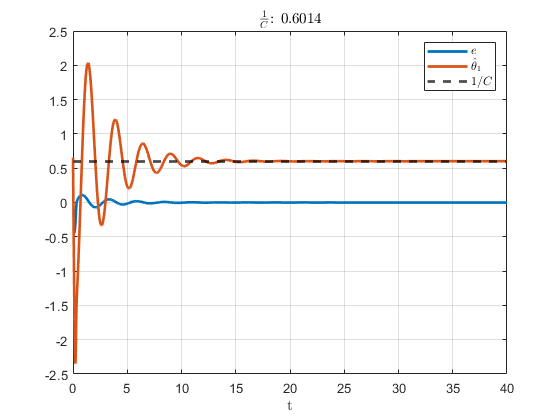

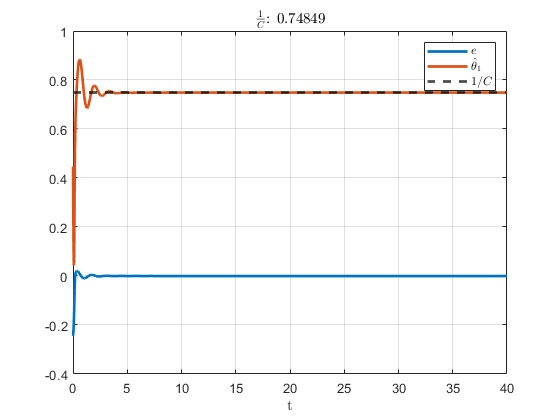

clearvars;
close all;

for i=1:2
    p.theta = rand(3,1);
    p.alpha = 8;     % alpha > 0
    p.qd = 5;
    
    % x0 = [q; dq]
    x0 = (rand(2,1)-0.5);   % Pick a random starting charge & current
    theta_hat_dot0 = rand(3,1); % Start with zeros for estimate
    
    y0 = [x0; theta_hat_dot0];
    
    tspan = [0 40]; 
    [t,y] = ode45(@(t,y) closedLoopDynamicsRLC(t,y,p), tspan, y0);
    
    figure()
    plot(t,y(:,1), t, y(:,3), "LineWidth", 2);
    hold on;
    yline(p.theta(1), '--k', "LineWidth", 2)
    
    xlabel("t", "Interpreter", "latex")   
    legend("$e$", "$\hat\theta_1$", "$1/C$", "Interpreter", "latex");

    title("$\frac{1}{C}$: " + p.theta(1), "Interpreter", "latex")
    grid on;
end

## Problem 2

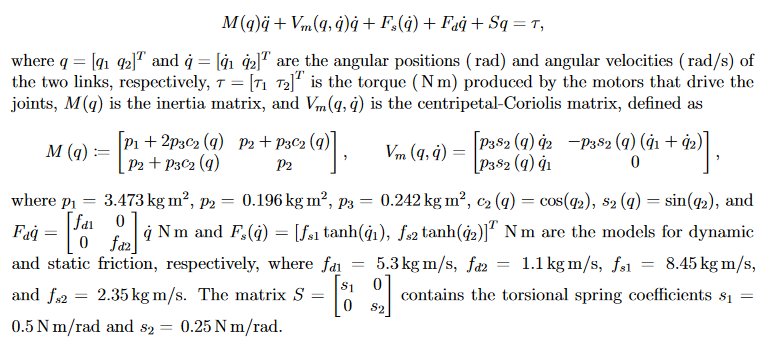

### 2.1 Assuming that the parameters are unkown, design a controller such that starting from any initial condition, the robot comes to rest at $q_d ={\left\lbrack \begin{array}{cc}
\pi  & \pi /2
\end{array}\right\rbrack }^T$

Closed loop dynamics: 


$$-M\left(q_d -e\right)\ddot{e} -V_m \left(q_d -e,-\dot{e} \right)\dot{e} +F_s \left(-\dot{e} \right)-F_d \dot{e} +S\left(q_d -e\right)=\tau$$



$$\ddot{e} =M^{-1} \left(q_d -e\right)\left(F_s \left(\dot{-e} \right)+S\left(q_d -e\right)-V_m \left(q_d -e,-\dot{e} \right)\dot{e} -F_d \dot{e} -\tau \right)$$


The system parameters $\theta ={\left\lbrack \begin{array}{ccccccccc}
p_1  & p_2  & p_3  & f_{\textrm{d1}}  & f_{\textrm{d2}}  & f_{\textrm{s1}}  & f_{\textrm{s2}}  & s_1  & s_2 
\end{array}\right\rbrack }^T$ are unkown.

Now, let $r=\dot{e} +\alpha e$  and $\tilde{\theta} =\theta -\hat{\theta}$, where $\hat{\theta}$ is our estimate of the sysem parameters. Define $z={\left\lbrack \begin{array}{ccc}
e & r & \tilde{\theta} 
\end{array}\right\rbrack }^T$ and $M\left(q_d -e\right)\dot{r} =Y_1 \left(e,r\right)\theta -\tau$


$$g\left(z\right)=\dot{z} =\left\lbrack \begin{array}{c}
\dot{e} \\
\dot{r} \\
\dot{\tilde{\theta} } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r-\alpha e\\
M^{-1} \left(q_d -e\right)\left(Y_1 \left(e,r\right)\theta -\tau \right)\\
-\dot{\hat{\theta} } 
\end{array}\right\rbrack$$


Let us define $V\left(z\right)=\frac{1}{2}e^T e+\frac{1}{2}r^T M\left(q_d -e\right)r+\frac{1}{2}\tilde{\theta^T } \tilde{\theta}$


$$\frac{\partial V\left(z\right)}{\partial z}=\left\lbrack \begin{array}{ccc}
e^T +\frac{1}{2}r^T \frac{\partial \left(M\left(q_d -e\right)r\right)}{\partial e} & r^T M\left(q_d -e\right) & {\tilde{\theta} }^T 
\end{array}\right\rbrack$$



$$\dot{V} \left(z\right)=\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)=\left(e^T +\frac{1}{2}r^T \frac{\partial \left(M\left(q_d -e\right)r\right)}{\partial e}\right)\left(r-\alpha e\right)+r^T M\left(q_d -e\right)\dot{r} +{\tilde{\theta} }^T \dot{\tilde{\theta} }$$



$$=e^T \left(r-\alpha e\right)+r^T \left(\frac{1}{2}\frac{\partial \left(M\left(q_d -e\right)r\right)}{\partial e}\left(r-\alpha e\right)+M\left(q_d -e\right)\dot{r} \right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$


Now define $Y_1 \left(e,r\right)\theta =M\left(q_d -e\right)\dot{r} +\tau$  and $Y_2 \left(e,r\right)\theta =\frac{1}{2}\frac{\partial \left(M\left(q_d -e\right)r\right)}{\partial e}\left(r-\alpha e\right)$


$$\dot{V} \left(z\right)=e^T \left(r-\alpha e\right)+r^T \left(Y_2 \left(e,r\right)\theta +Y_1 \left(e,r\right)\theta -\tau \right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$



$$\dot{V} \left(z\right)=e^T r-e^T \alpha e+r^T \left(Y_1 \left(e,r\right)\theta +Y_2 \left(e,r\right)\theta -\tau \right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$


Now we need to design $\tau$ and $\dot{\hat{\theta} }$ such that $\dot{V} \left(z\right)$is negative semidefinite or negative definite. Let us choose $\tau =Y_1 \left(e,r\right)\hat{\theta} +Y_2 \left(e,r\right)\hat{\theta} +e+r$.


$$\dot{V} \left(z\right)=e^T r-e^T \alpha e+r^T \left(Y_1 \left(e,r\right)\tilde{\theta} +Y_2 \left(e,r\right)\tilde{\theta} -e-r\right)-{\tilde{\theta} }^T \dot{\hat{\theta} }$$



$$=e^T r-r^T e-e^T \alpha e-r^T r+r^T \left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)\tilde{\theta} -{\tilde{\theta} }^T \dot{\hat{\theta} }$$



$$=-e^T \alpha e-r^T r+r^T \left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)\tilde{\theta} -\dot{{\hat{\theta} }^T } \tilde{\theta}$$


By defining ${\dot{\hat{\theta} } }^T =r^T \left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)$, we show that $\dot{V} \left(z\right)\le 0\;\;\;\forall z\in \Re^{13}$


$$\dot{V} \left(z\right)=-e^T \alpha e-r^T r$$


**Conclusion for controller design:**

Defining $\tau =\left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)\hat{\theta} +e+r$ and $\dot{\hat{\theta} } ={\left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)}^T r$ makes $\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)$ negative semidefinite and shows the origin to be at least Lyupanov stable. Next, we will apply the invariance principle to conclusively determine the type of stability.

$\dot{V} \left(z\right)\le 0$ on the line $z={\left\lbrack \begin{array}{ccccc}
0 & 0 & 0 & 0 & \tilde{\theta} 
\end{array}\right\rbrack }^T$. See below for an analysis of the hypotheses of Corollary 90.

**1.)** $D\subset\mathbb{R}^{13}$ is an open set. Here, $D=\mathbb{R}^{13}$ as $V\left(z\right)>0\;$  $\forall z\in\mathbb{R}^{13}$ and $\dot V(z) \leq 0 ~~\forall z\in\mathbb{R}^{13}$

**2.) **$\dot{z} =g\left(z\right)$ is locally Lipschitz. This is true as all components of $g\left(z\right)={\left\lbrack \begin{array}{ccc}
\dot{e}  & \dot{r}  & \dot{\tilde{\theta} } 
\end{array}\right\rbrack }^T$ are locally Lipschitz.

**3.)** $V\left(z\right)$ is continuously differentiable

**4.) **By Claim 64 and acknowledging that $V\left(z\right)$ is radially unbounded, given any $\beta >0$, $\Omega_{\beta }^{\prime }$ is a filled ellipse, compact, connected, and in $D=\mathbb{R}^{13}$ and is positively invariant. Let $\Omega =\Omega_{\beta }^{\prime }$ for any $\beta >0$. We can show that $V\left(z\right)$is radially unbounded as $M\left(q_d -e\right)$ is positive definite thus $z\to \infty \;\Longrightarrow V\left(z\right)\to \infty$.

**5.) **$\dot{V} \left(z\right):=\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)\le 0,\;\;\;\forall x\in \Omega$. This is true as $\dot{V} \left(z\right)$ was designed to be negative semidefinite.

**6.)** $E=\left\lbrace z\in \Omega \;|\;\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)=0\right\rbrace =\Omega \cap \left\lbrace \left\lbrack \begin{array}{c}
e\\
r\\
\tilde{\theta} 
\end{array}\right\rbrack \in R^{13} \;\;|\;\;e,r=0\right\rbrace$

**7.) **Find $M\subset E$, where $M$ is the largest invariant set in $E$.

First, we need to compute $Y_1 \left(e,r\right)$ and $Y_2 \left(e,r\right)$. The following code snippets were adapted from Handout 3.

**Compute **$Y_1 \left(e,r\right)$ **and save to a file**

clearvars;
syms theta [9 1]
syms x [4 1]
syms tau [2 1] 
syms alpha 
syms qd [2 1]

e = x(1:2);
r = x(3:4) + alpha*e;

q = qd-e;

M = [theta1+2*theta3*cos(q(2)),  theta2+theta3*cos(q(2));
     theta2+theta3*cos(q(2)),    theta2                 ];
Vm = [theta3*sin(q(2))*-x4,  -theta3*sin(q(2))*(-x3-x4);
      theta3*sin(q(2))*-x3,   0                        ];
Fd = diag(theta(4:5));
Fs = theta(6:7).*tanh(-x(3:4));
S = diag(theta(8:9));


f1 = Fs+S*q(1:2)-Vm*x(3:4)-Fd*x(3:4)+M*alpha*x(1:2);

Y1 = sym(zeros(numel(f1),numel(theta)));

for i=1:numel(f1)
    for j=1:numel(theta)
        temp = coeffs(f1(i,:),theta(j),'All');
        if numel(temp) == 2
            Y1(i,j) = temp(1);
        end
    end
end

matlabFunction(simplify(Y1), 'File', 'Y1', 'Vars', {x,alpha,qd});

**Now compute **$Y_2 \left(e,r\right)$ **and save to a file**

f2 = 1/2*[diff(M*r, x1), diff(M*r, x2)]*(r-alpha*e);
Y2 = sym(zeros(numel(f2),numel(theta)));

for i=1:numel(f2)
    for j=1:numel(theta)
        temp = coeffs(f2(i,:),theta(j),'All');
        if numel(temp) == 2
            Y2(i,j) = temp(1);
        end
    end
end

matlabFunction(simplify(Y2), 'File', 'Y2', 'Vars', {x,alpha,qd});

Now rewrite the system dynamics to include our control terms:


$$\dot{e} =r-\alpha e$$



$$\dot{r} =M^{-1} \left(q_d -e\right)\left(Y_1 \left(e,r\right)\theta -\tau \right)=M^{-1} \left(q_d -e\right)\left(Y_1 \left(e,r\right)\tilde{\theta} -Y_2 \left(e,r\right)\hat{\theta} -e-r\right)$$



$$\dot{\tilde{\theta} } =-\dot{\hat{\theta} } =-{\left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)}^T r$$


As the origin is an equilibrium point, we know that $M$ must include the set $\left\lbrace \overrightarrow{0} \right\rbrace$.  To see if we can find a larger invariant set, let $\zeta^0 =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
\tilde{\theta} 
\end{array}\right\rbrack$. Then at $t=0$, $g\left(z\right)=\left\lbrack \begin{array}{c}
r-\alpha e\\
M^{-1} \left(q_d -e\right)\left(Y_1 \left(e,r\right)\tilde{\theta} -Y_2 \left(e,r\right)\hat{\theta} -e-r\right)\\
-{\left(Y_1 \left(e,r\right)+Y_2 \left(e,r\right)\right)}^T r
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
M^{-1} \left(q_d -e\right)\left(Y_1 \left(e,r\right)\tilde{\theta} -Y_2 \left(e,r\right)\hat{\theta} \right)\\
0
\end{array}\right\rbrack \ldotp$ We need to find a $\zeta^0$ which will set $g\left(z\right)=\overrightarrow{0}$at $t=0$. The following snippet of code shows $Y_1 \left(e,r\right)\tilde{\theta}$ and $Y_2 \left(e,r\right)\hat{\theta}$ at $\left\lbrack \begin{array}{c}
e\\
r
\end{array}\right\rbrack =\overrightarrow{0}$.

clearvars;
syms z [13 1] 
syms qd [2 1] 
syms that [9 1]
syms alpha
e = z(1:2);
r = z(3:4);
y1 = Y1([e;r-e*alpha], alpha, qd);
y2 = Y2([e;r-e*alpha], alpha, qd);

y1 = subs(y1, z(1:4), zeros(4,1))*z(5:13)

$$y1 = \left(\begin{array}{c} {\mathrm{qd}}_{1}\,z_{12}\\ {\mathrm{qd}}_{2}\,z_{13} \end{array}\right)$$

y2 = subs(y2, z(1:4), zeros(4,1))*that

$$y2 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

It is shown that $Y_2 \left(e,r\right)\hat{\theta} =\overrightarrow{0}$ if $\left\lbrack \begin{array}{c}
e\\
r
\end{array}\right\rbrack =\overrightarrow{0}$, however $Y_1 \left(e,r\right)\tilde{\theta}$ is still dependent on $q_{\mathrm{d1}} \tilde{\theta_8 }$ and $q_{\mathrm{d2}} \tilde{\theta_9 }$.

Thus $M=\left\lbrace \left\lbrack \begin{array}{c}
e_1 \\
e_2 \\
r_1 \\
r_2 \\
\tilde{\theta_1 } \\
\tilde{\theta_2 } \\
\tilde{\theta_3 } \\
\tilde{\theta_4 } \\
\tilde{\theta_5 } \\
\tilde{\theta_6 } \\
\tilde{\theta_7 } \\
\tilde{\theta_8 } \\
\tilde{\theta_9 } 
\end{array}\right\rbrack \in \Re^{13} \;\;|\;\;e,r,\tilde{\theta_8 } ,\tilde{\theta_9 } =0\right\rbrace$  and $M\subset E$. Given any $\zeta^0 \in \Omega$, $\lim_{t\to \infty } \;\mathrm{dist}\left(\phi \left(t,\zeta^0 \right),M\right)=0$ and $\lim_{t\to \infty } \;\phi_e \left(t,\zeta^0 \right)=0$. In other words, the the angular position will approach the setpoint when $\zeta^0 \in \Omega$.

As $V\left(z\right)$is radially unbounded, we can pick an arbitrarily large $\beta$ such that $\zeta^0 \in \Omega_{\beta }^{\prime }$. Letting $\Omega =\Omega_{\beta }^{\prime }$ shows **global asymptotic stability (GAS).**

### 2.2 Bonus

 In order to show that $\left\lbrack \begin{array}{cc}
\hat{\theta_8 }  & \hat{\theta_9 } 
\end{array}\right\rbrack$ converges to $\left\lbrack \begin{array}{cc}
s_1  & s_2 
\end{array}\right\rbrack$, let us use $Y_1 \left(e,r\right)$. We defined $Y_1 \left(e,r\right)$ such that $Y_1 \left(e,r\right)\theta =M\left(q_d -e\right)\dot{r} +\tau$. We've already shown GAS of the origin. In order for $r$ to stay at the origin, $\dot{r}$ must also be $0$. This implies that 


$$0=Y_1 \left(e,r\right)\theta -Y_1 \left(e,r\right)\hat{\theta} -Y_2 \left(e,r\right)\hat{\theta} -e-r$$


$0=Y\left(\overrightarrow{0} ,\overrightarrow{0} \right)\tilde{\theta}$           As $e,r=0$


$$0=\left\lbrack \begin{array}{ccccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 0 & q_{\mathrm{d1}}  & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & q_{\mathrm{d2}} 
\end{array}\right\rbrack \tilde{\theta}$$



$$\left\lbrack \begin{array}{c}
q_{\mathrm{d1}} \tilde{\theta_8 } \\
q_{\mathrm{d2}} \tilde{\theta_9 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$
 

Thus, we have shown that $\left\lbrack \begin{array}{c}
q_{\mathrm{d1}} \\
q_{\mathrm{d2}} 
\end{array}\right\rbrack \not= \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \Longrightarrow \left\lbrack \begin{array}{c}
\tilde{\theta_8 } \\
\tilde{\theta_9 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$, as $t\to \infty$. This shows that $\left\lbrack \begin{array}{c}
\hat{\theta_8 } \\
\hat{\theta_9 } 
\end{array}\right\rbrack$ converges to $\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack$.

### 2.3 Simulate the controller to show that it works as expected. 

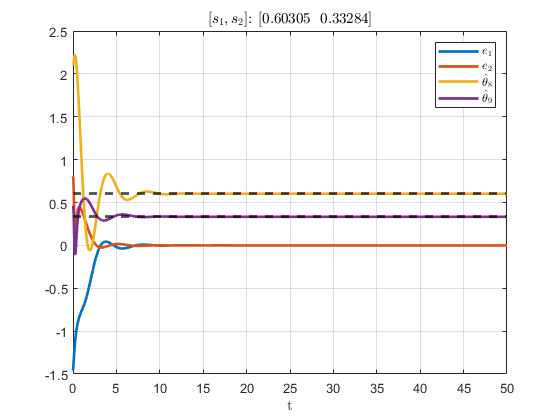

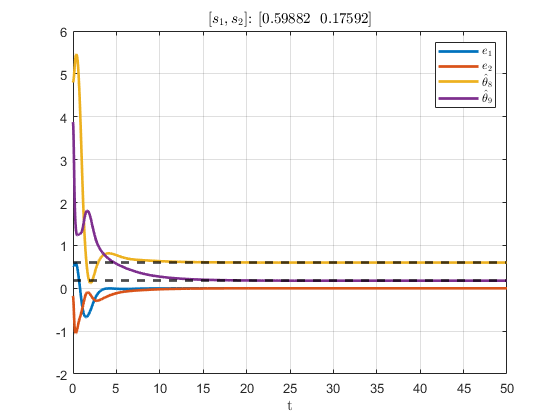

clearvars;

for i = 1:2
    % Initialize theta to be a random value.
    p.theta = [3.473;0.196;0.242;5.3;1.1;8.45;2.35;0.5;0.25];
    
    % Bias theta to be within 50% of the standard parameters
    p.theta  = p.theta + p.theta.*(1.0.*rand(9,1) - 0.5);
    
    p.alpha = 1;     % alpha > 0
    
    
    p.qd = [pi; pi/2];
    
    % x0 = [q; dq]
    x0 = pi*(rand(4,1)-0.5);     % Pick a random starting positions and velocities
    
    % Random initial guess for theta_hat
    theta_hat_dot0 = 5*rand(9,1);
    
    y0 = [x0; theta_hat_dot0];
    
    tspan = [0 15];
    [t,y] = ode45(@(t,y) closedLoopDynamicsDDR(t,y,p), tspan, y0);
    
    theta_tilde = mat2str(p.theta - y(end,5:13)', 2);
    
    figure()
    plot(t,y(:,1:2), t,y(:,12:13), "LineWidth", 2);
    hold on;
    yline(p.theta(8:9), '--k', "LineWidth", 2)
    
    xlabel("t", "Interpreter", "latex")   
    legend("$e_1$", "$e_2$", "$\hat\theta_8$", "$\hat\theta_9$", "Interpreter", "latex");

    title("$\left[s_1, s_2 \right]$: $\left[" + p.theta(8) + "~~" + p.theta(9)+ "\right]$", "Interpreter", "latex")
    grid on;
end

## Problem 3

Assume that

1.) $f:\Re^2 \to \Re^2$ is a locally Lipschitz function with $f\left(0\right)=0$.

2.) $V\left(x\right)=\frac{{\left(x_1 +x_2 \right)}^2 }{1+{\left(x_1 +x_2 \right)}^2 }+{\left(x_1 -x_2 \right)}^2$

3.) $\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)=-x_2^2$

4.) whenever $x_1 \;\not= \;0$, we know that $\dot{x_2 } \;\not= \;0$.

Find the largest estimate you can for the region of attraction of the origin. you can use a computer to compute sublevel sets and plot contour plots. Submit a plot of the region of attraction.

### **3.1 Find the largest estimate you can for the region of attraction**

$E=\left\lbrace x\in \Omega \;|\;x_2 =0\right\rbrace$.  As $x_1 \;\not= \;0\;\Longrightarrow \dot{x_2 } \;\not= \;0$, $M=\left\lbrace \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \right\rbrace$. This implies asymptotic stability at the origin, though we need to define the region of attraction. The region of attraction $\Omega$ is clearly not $\mathbb{R}^2$ as $V\left(x\right)$is not radially unbounded. Let us look at the simple case of the line $\gamma =x_2 =x_1$, on which $V\left(x\right)=\frac{4\gamma^2 }{1+4\gamma^2 }$.


$$\begin{array}{l}
\lim \;\frac{4\gamma^2 }{1+4\gamma^2 }=1\\
\gamma \to \infty 
\end{array}$$


Thus, any contours greater than 1 will never reach the line $x_1 =x_2$ and will not include the origin. The region of attraction of the origin is defined as $\Omega =\left\lbrace x\in \Re^2 \;\;|\;\;V\left(x\right)<1\right\rbrace$. 

### **3.2 Plot the contour plots**

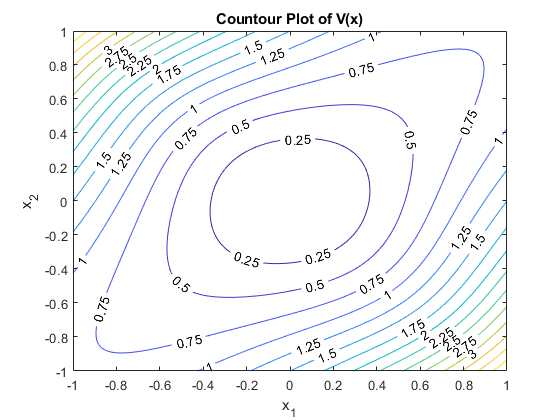

clearvars;

syms V(x,y)
V(x,y) = simplify((x+y)^2/(1+(x+y)^2)+(x-y)^2);
v = matlabFunction(V);

d = 100;
range = 1;
figure()
x = linspace(-range,range,2*range*d);
y = x;

[X,Y] = meshgrid(x,y);

figure()
contour(X,Y,v(X,Y), "LevelStep", 0.25, "ShowText", 'on')
xlabel("x_1")
ylabel("x_2")
title("Countour Plot of V(x)")

### 3.3 Plot the region of attraction

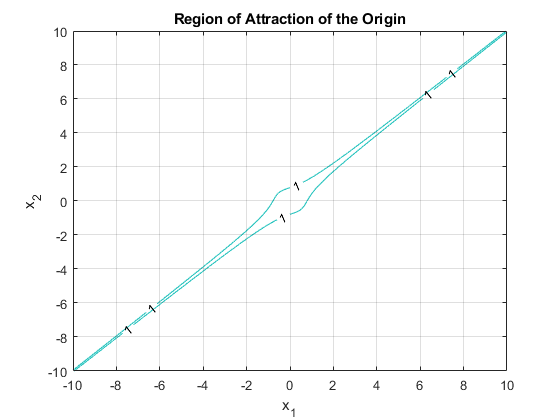

range = 10;
figure()
x = linspace(-range,range,2*range*d);
y = x;

[X,Y] = meshgrid(x,y);
figure()
contour(X,Y,v(X,Y), "LevelList", [1], "ShowText", 'on')
xlabel("x_1")
ylabel("x_2")
title("Region of Attraction of the Origin")
grid on

## Problem 4

The Block Equation, commonly used in nuclear magnetic resonance (NMR) and magnetic resonance imaging (MRI), is a model for the magnetization experinced by nuclei of atoms when exposed to a magnetic field. Assuming a constant magnetic field, $B_0$, along th elongitudinal axis $z$, the $x,y$, and $z$ components of magnetization evolve according to 


$$\dot{M_x } =-\frac{1}{T_2 }M_x +\gamma B_0 M_y$$



$$\dot{M_y } =-\frac{1}{T_2 }M_y -\gamma B_0 M_x$$



$$\dot{M_z } =-\frac{1}{T_1 }\left(M_z -M_0 \right)$$


where $\gamma$ is the gyromagnetic ratio that depends on the chemical strucutre of the atom. Trajecotries generated by this model precess in the transverse $\textrm{xy}$ plane, decaying with time constant $T_2$. Simultaneously the longitudinal component returns to the equilibrium magnetizaiton $M_0$ with time constant $T_1$

### 4.1 Find a candidate Lyapunov function to get the best possible stability result for the equilibrium ${\left\lbrack \begin{array}{ccc}
M_x  & M_y  & M_z 
\end{array}\right\rbrack }^T ={\left\lbrack \begin{array}{ccc}
0 & 0 & M_0 
\end{array}\right\rbrack }^T$

Define $x=\left\lbrack \begin{array}{c}
M_x \\
M_y \\
M_z 
\end{array}\right\rbrack$and $f\left(x\right)=\dot{x} =\left\lbrack \begin{array}{c}
-\frac{1}{T_2 }M_x +\gamma B_0 M_y \\
-\frac{1}{T_2 }M_y -\gamma B_0 M_x \\
-\frac{1}{T_1 }\left(M_z -M_0 \right)
\end{array}\right\rbrack$, where $f\left(\left\lbrack \begin{array}{c}
0\\
0\\
M_0 
\end{array}\right\rbrack \right)=0$.

As the origin is not an equilibrium point, we must perform a linear transformation before applying Lyupanov analysis.

Define $z=\left\lbrack \begin{array}{c}
M_x \\
M_y \\
M_z -M_0 
\end{array}\right\rbrack$ and $g\left(z\right)=\dot{z} =\left\lbrack \begin{array}{c}
-\frac{1}{T_2 }z_1 +\gamma B_0 z_2 \\
-\frac{1}{T_2 }z_2 -\gamma B_0 z_1 \\
-\frac{1}{T_1 }z_3 
\end{array}\right\rbrack$. Now $g\left(\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \right)=0$ and Lyupanov analysis may be applied.

Define $V\left(z\right)$ of the quadratic form $V\left(z\right)=\frac{1}{2}z^T Az$, where $A=\textrm{diag}\left(\left\lbrack \begin{array}{ccc}
a_1  & a_2  & a_3 
\end{array}\right\rbrack \right)$.


$$\frac{\partial V\left(z\right)}{\partial z}=z^T A$$



$$\dot{V} \left(z\right)=\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)=z^T A\left\lbrack \begin{array}{c}
-\frac{1}{T_2 }z_1 +\gamma B_0 z_2 \\
-\frac{1}{T_2 }z_2 -\gamma B_0 z_1 \\
-\frac{1}{T_1 }z_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
z_1 a_1  & z_2 a_2  & z_3 a_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-\frac{1}{T_2 }z_1 +\gamma B_0 z_2 \\
-\frac{1}{T_2 }z_2 -\gamma B_0 z_1 \\
-\frac{1}{T_1 }z_3 
\end{array}\right\rbrack$$



$$=z_1 a_1 \left(-\frac{1}{T_2 }z_1 +\gamma B_0 z_2 \right)+z_2 \alpha_2 \left(-\frac{1}{T_2 }z_2 -\gamma B_0 z_1 \right)+z_3 a_3 \left(-\frac{1}{T_1 }z_3 \right)$$



$$=-\frac{a_1 }{T_2 }z_1^2 -\frac{a_2 }{T_2 }z_2^2 -\frac{a_3 }{T_1 }z_3^2 +\gamma B_0 z_1 z_2 \left(a_1 -a_2 \right)$$


$\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)<0\;\;\;\forall z\in D\backslash \left\lbrace 0\right\rbrace$ iff $a_1 ,a_2 ,a_3 >0$ and $a_1 =a_2$.

Thus, the simplified equation is given as $V\left(z\right)=\frac{1}{2}a_0 z_1^2 +\frac{1}{2}a_0 z_2^2 +\frac{1}{2}a_3 z_3^2$  and $\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)=-\frac{a_0 }{T_2 }\left(z_1^2 +z_2^2 \right)-\frac{a_3 }{T_1 }z_3^2$

With the added constraints, $\dot{V} \left(z\right)$ is negative definite for all $z\in\mathbb{R}^3$. Thus, $D = \mathbb{R}^3$ and the system is **GAS **by the Barbashin-Krasovskii Theorem**. **See below for a verification of the hypotheses of the theorem.

**1.) The origin is an equilibrium point of **$\dot{z} =g\left(z\right)$ where $g:~~\mathbb{R}^n\rightarrow\mathbb{R}^n$ is locally Lipschitz continous. This is true as $z$ transformed such that the origin is an equilibrium point. $g\left(x\right)$ is locally Lipschitz continous if $T_{1,2} \;\not= \;0$.

**2.)** $V:~~\mathbb{R}^n\rightarrow\mathbb{R}^n$ is continuously differentiable and positive definite.$V\left(z\right)$ is of the quadratic form, so this hypothesis is true.

**3.) **$||z||\to \infty \;\Longrightarrow V\left(z\right)\to \infty$ ($V\left(z\right)$ is radially unbounded). $V\left(z\right)$ is of the quadratic form, so this hypothesis is true.

**4.)** $\frac{\partial V\left(z\right)}{\partial z}g\left(z\right)<0\;$  $\forall x\in\mathbb{R}^n \backslash \{0\}$. $\dot{V} \left(z\right)$ is negative definite if $V\left(z\right)=\frac{1}{2}a_0 z_1^2 +\frac{1}{2}a_0 z_2^2 +\frac{1}{2}a_3 z_3^2$. 

function [dy] = closedLoopDynamicsRLC(t, x, p)
    p.Y = [p.qd, -x(2), p.alpha*x(2)];
    p.r = x(2) + p.alpha*x(1);
    
    dx = openLoopDynamicsRLC(t, x, controlRLC(t,x,p), p);
    theta_hat_dot = updateLawRLC(t, x, p);
    dy = [dx; theta_hat_dot];
end

function [u] = controlRLC(~, x, p)
    u = p.Y*x(3:5) + x(2) + x(1);
end

% x = [e; e_dot; theta_hat_dot], where e = qd - q
function [dx] = openLoopDynamicsRLC(~,x,u,p)
    dx(1,:) = x(2);
    dx(2,:) = (1/p.theta(3))*((p.qd-x(1))*p.theta(1) - p.theta(2)*x(2) - u);
end

function theta_hat_dot = updateLawRLC(~, ~, p)
    theta_hat_dot = p.r*p.Y';
end

function [dy] = closedLoopDynamicsDDR(t, x, p)
    e  = x(1:2);
    de = x(3:4);
    
    a = p.alpha;
    p.r = de + a*e;
    
    dx = openLoopDynamicsDDR(t, x, controlDDR(t, x, p), p);
    theta_hat_dot = updateLawDDR(t, x, p);
    dy = [dx;theta_hat_dot];
end

function [u] = controlDDR(~, x, p)
    e = x(1:2);
    r = p.r;
    
    u = (Y1(x(1:4), p.alpha, p.qd) + Y2(x(1:4), p.alpha, p.qd))*x(5:13) + e + r;
end

% x = [e; e_dot; theta_hat_dot], where e = qd - q
function [dx] = openLoopDynamicsDDR(~,x,u,p)
    p1  = p.theta(1);
    p2  = p.theta(2);
    p3  = p.theta(3);
    fd1 = p.theta(4);
    fd2 = p.theta(5);
    fs1 = p.theta(6);
    fs2 = p.theta(7);
    s1  = p.theta(8);
    s2  = p.theta(9);
    
    q = p.qd-x(1:2);
    dq = -x(3:4);
    
    M = [p1+2*p3*cos(q(2)),  p2+p3*cos(q(2));
         p2+p3*cos(q(2)),    p2];
    
    S = diag([s1, s2]);
    
    Fs = [fs1*tanh(dq(1)); fs2*tanh(dq(2))];
    
    Fd = diag([fd1, fd2]);
    
    sq2 = sin(q(2));
    Vm = [p3*sq2*dq(2),  -p3*sq2*(dq(1)+dq(2));
          p3*sq2*dq(1),  0];
    
    dx(1:2,:) = x(3:4);
    dx(3:4,:) = M\(Fs+S*q+Vm*dq+Fd*dq-u);
end

function theta_hat_dot = updateLawDDR(~, x, p)
    theta_hat_dot = (Y1(x(1:4),p.alpha,p.qd) + Y2(x(1:4), p.alpha, p.qd))'*p.r;
end